clear
clc
clf
[mode_freq,path]=uigetfile('.txt');
mode_freq=fullfile(path,mode_freq);
mode_freq=importdata(mode_freq);%kokotabuntitlekesu
mode_freq=mode_freq.data(:,3)

mode_freq = 	1.0e+03 *

    1.8523
    1.8523
    2.0855
    2.0855
    3.4430
    3.4430
    3.5107
    3.5107


[mode_files]=uigetfile('*.txt',"MultiSelect","on");
N=length(mode_files);%これが↓のROM次元数にあたる。（固有振動数の数）
Target_N_range=6;


NodeNum=144;%これは、データ点数
hosei=sqrt(519/N);%これは、モデルの節数/ROM次元数 モデルの説点数もファイルから取れるようにしたい.
DelegateNodeNum=zeros(1,N);
Disps=zeros(N,NodeNum);
f1=cell([1,N]);
for i=1:1:N
    temp_f=figure();
    f1{i}=temp_f;
    temp_f.Visible="off";
    %subplot(2,floor(N/2)+1,i)
    file=fullfile(path,mode_files{i});
    Zdisp=importdata(file);
    Node=Zdisp.data(:,1);
    X=Zdisp.data(:,2);%[mm]
    Y=Zdisp.data(:,3);%[mm]
    Z=Zdisp.data(:,4);%[mm]
    THETA=atan2(Z,Y);
    Disp=Zdisp.data(:,5)/1000*hosei;%[m]
    %scatter3(Y,Z,Disp,".")
    polarplot(THETA,Disp./max(abs(Disp))+1);
    rlim([-2,2]);
    title(string(mode_freq(i))+"Hz");
    hold on
    if i<Target_N_range+1%高次を適当に取る場合
    %%%%%ここから代表点とり(振幅マックスの点)%%%%%%%%%
    
    
    [data,index]=sort(Disp,'descend');
    index=setdiff(index,DelegateNodeNum,'stable');
    DelegateNodeNum;
    
    DelegateNodeNum(i)=index(2);
   
    %%%%%%%ここまで代表点とり%%%%%
    else
    %%%代表点を任意でとる%%%
    
        
        DelegateNodeNum(i)=chooseDlg(Y,Z,X,Disp,DelegateNodeNum,i);
    
    end
    %%%代表点を任意でとる場合%%%
    
    Disps(i,:)=Disp;
end
mode_shapes_angle=THETA(DelegateNodeNum);

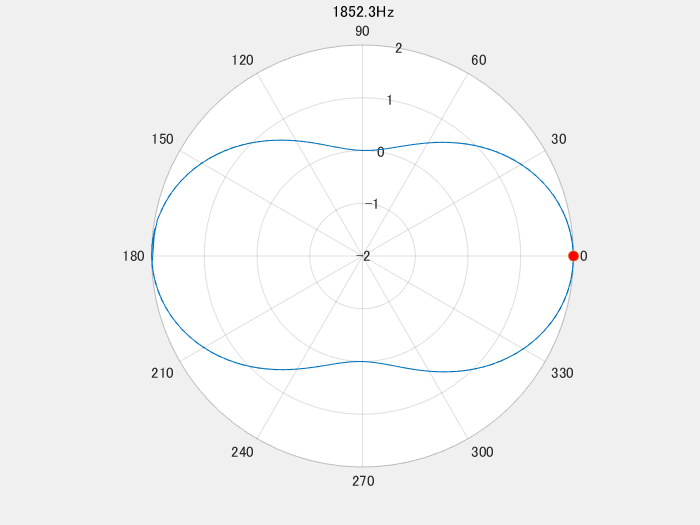

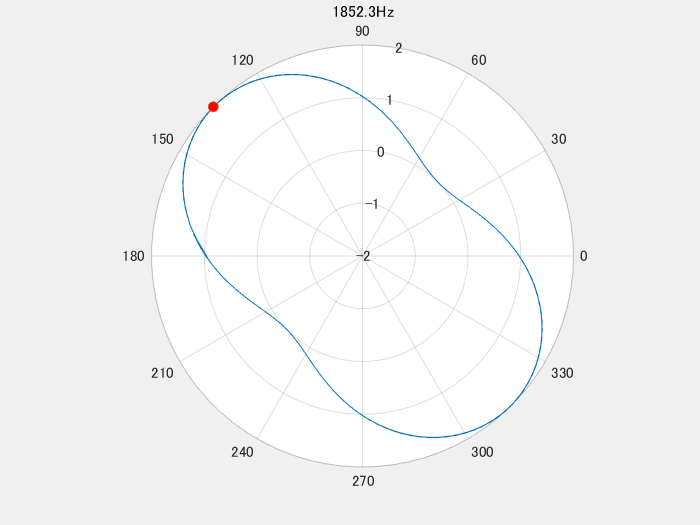

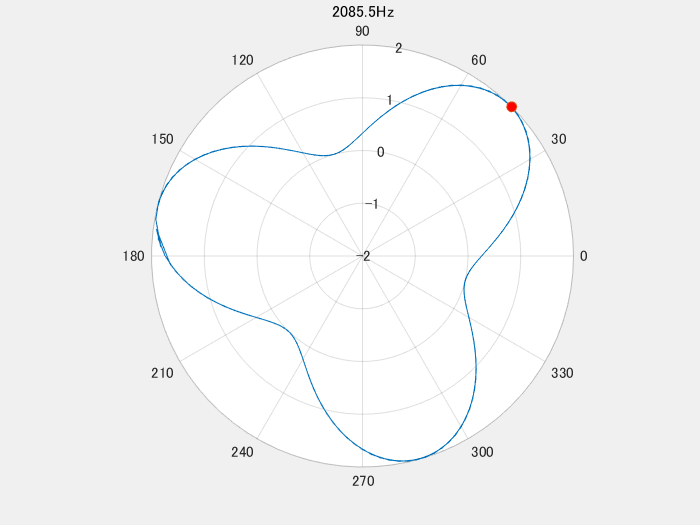

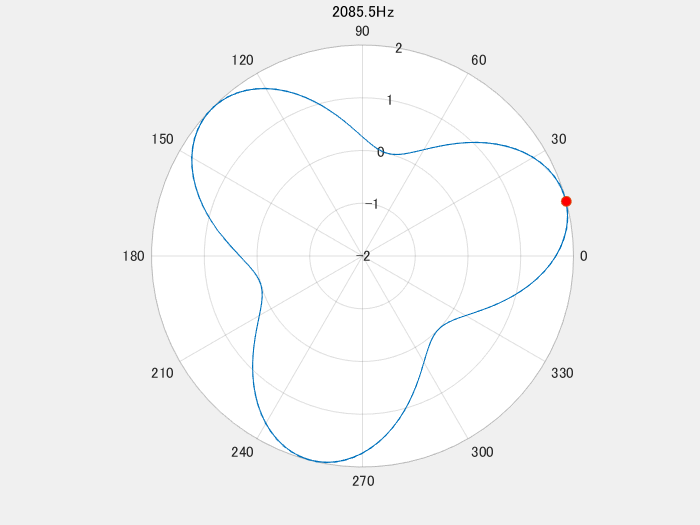

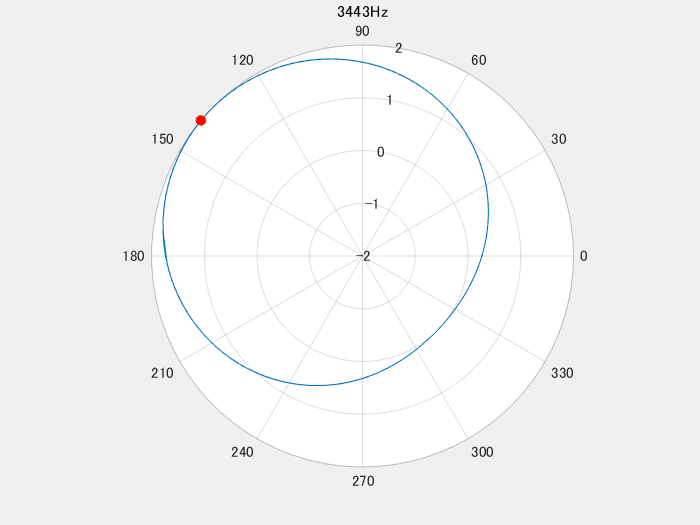

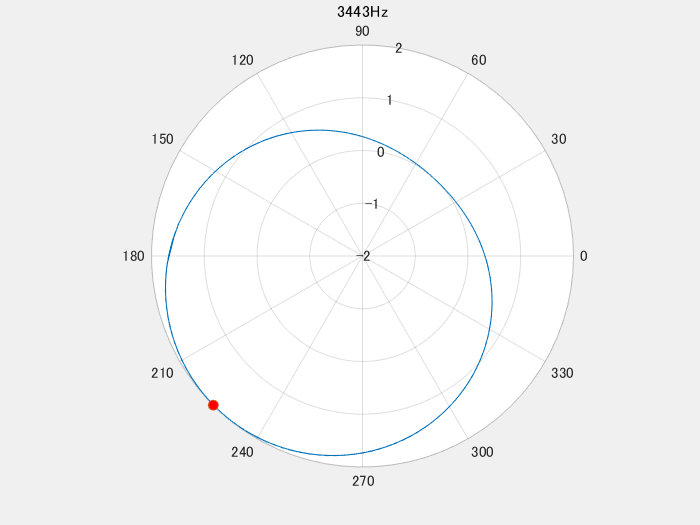

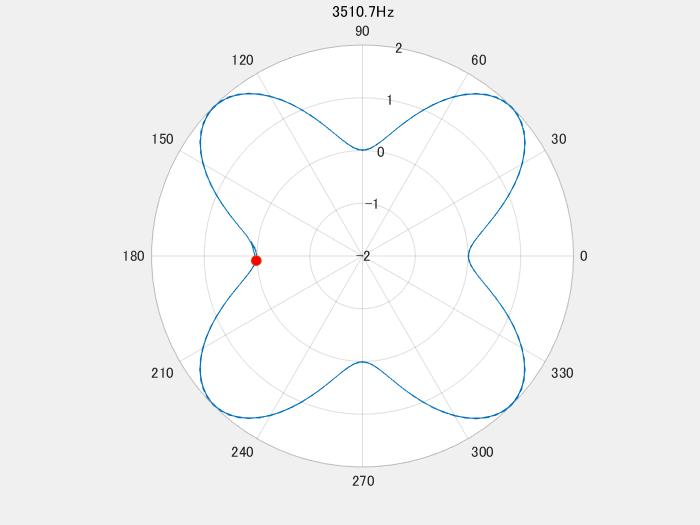

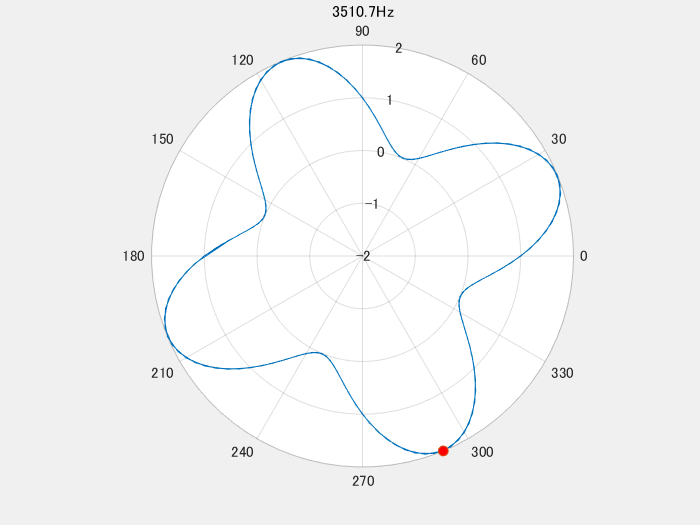


%sgtitle('Mode shapes')
mode_shapes=zeros(N,N);
%ここは代表点をプロット
%color=[1 0 0;0 0 1;0 1 0;1 1 0; 0 1 1;1 0 1];
for i=1:1:N
    Disp=Disps(i,:);
    mode_shapes(:,i)=Disp(DelegateNodeNum);
    figure(f1{i})
    f1{i}.Name='Mode_Shape'+string(i);
    %subplot(2,floor(N/2)+1,i)
    hold on
    %xlabel("X[mm]")
    %ylabel("Y[mm]")
    %zlabel("Displacement[mm]")
    %scatter3(Y(DelegateNodeNum(i)),Z(DelegateNodeNum(i)),Disps(i,DelegateNodeNum(i)),50,color(i,:),"filled")    
    polarplot(THETA(DelegateNodeNum(i)),Disps(i,DelegateNodeNum(i))./max(abs(Disps(i,:)))+1,'o','MarkerFaceColor',"red")
end

%dim = [.5 .1 .3 .3];
%str = "red:1st"+newline+"blue:2nd"+newline+"green:3rd"+newline+"yellow:4th"+newline+"cyan:5th"+newline+"magenta:6th";
%annotation('textbox',dim,'String',str,'FitBoxToText','on');


[mass,K,ms]=ROM_func(mode_shapes,mode_freq);

now = 0.2005

[Mm,Km,ms_norm_rep_point_amp]=modalMassK(mass,K,ms,mode_freq);%modalMassKは等価質量としてのモード質量を出しとる。
f2=cell([1,N]);%figure('Name','Mode Shapes of Lumped mass System','NumberTitle','off');
f3=figure();figure('Name','Delegation Points of Each Modes','NumberTitle','off');
f4=figure();figure('Name','Physical Mass','NumberTitle','off');
f5=figure();figure('Name','Physical Stiffness','NumberTitle','off');
f6=figure();figure('Name','FRF of Lumped Mass System','NumberTitle','off');
f7=figure();figure('Name','Modal Stiffness','NumberTitle','off');
%visualizeModalMass(Mm,Km,f7);
%visualizeMode(mode_shapes,ms,f2,mode_shapes_angle)
%visualizePhysicalMass(X,Y,Z,DelegateNodeNum,mass,K,f3,f4,f5)


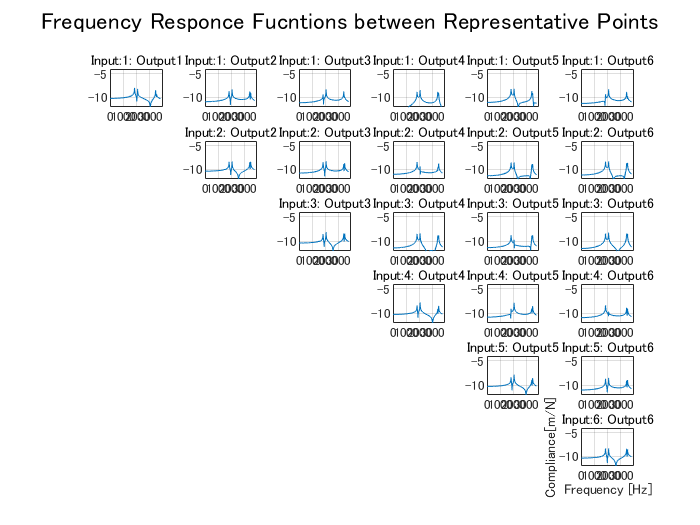

zeta=0.001;
[a,b]=return_ab(mode_freq,zeta);
freq=linspace(0,mode_freq(end)+300,500);
FRF_org=multiFRF(ms_norm_rep_point_amp,Mm,Km,a,b,freq,f6,Target_N_range);%ここで、正規化したモードを入れるのは、Mmだの（等価質量でもある）を使ってることから。

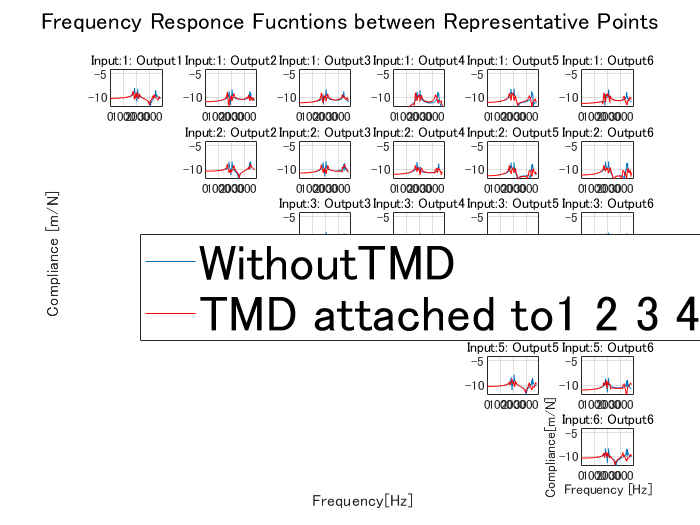


c=["red","blue","green","black","yellow","cyan","magenta"];
TMDnum=8;
pattern=TMDArrangement(N,TMDnum,DelegateNodeNum,Y,Z);arrange=[1:1:N];
strpatern="TMD attached to"+join(string(arrange(pattern==1)));
figure(f6)
alpha=0.01;

Target_mode=1;
p=Target_N_range;%length(mode_freq);
damperMass=alpha*Mm*diag(pattern);%massはモーダルマスに合している
damperK=damperMass*(diag(2*pi*mode_freq(:)).^2);%Kは対象モードに合わす？
damperK=damperK.*pattern;%ｋはｍの値とモード不利クエン氏―から出してる
beta=0.01;%m,kは固有振動数に合わせてチューンしてる
damperC=2*beta*sqrt(damperMass.*damperK);damperC=damperC.*pattern;

FRF=return_FRF(mass,K,a*mass+b*K,damperMass,damperK,damperC,freq);
hold on
bango=0;
for i=1:1:p
    for j=1:1:p
        bango=bango+1;

        if i>j
            continue
        end
    subplot(p,p,bango)
    hold on
    x=reshape(abs(FRF(i,j,:)),1,length(freq));
    plot(freq,log10(x),c(1));

    end
    
    
end


lgd=legend("WithoutTMD",strpatern,'Location',"westoutside",'FontSize',30);
lgd.Position(1)=0.2;
lgd.Position(2)=0.35;
han=axes(gcf,'visible','off');
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    ylabel(han,'Compliance [m/N]');
    xlabel(han,'Frequency[Hz]');

   
folder_name="TMD=1st_Pattern="+strpatern+"_Mass="+string(m)+"_freq=set_alpha="+string(alpha)+"_beta="+string(beta);
cd result\
mkdir("TMD=1st_Pattern="+strpatern+"_Mass="+string(m)+"_freq=set_alpha="+string(alpha)+"_beta="+string(beta))
cd(folder_name)
f6.Position = [100 100 2000 2000];
saveas(f6,'FRF',"png")
saveas(f6,"FRF",'fig')
f1.Position = [100 100 2000 2000];
saveas(f1,"Mode_shapes_dlgPoints",'fig')
saveas(f1,"Mode_shapes_dlgPoints",'png')
cd ..
cd ..